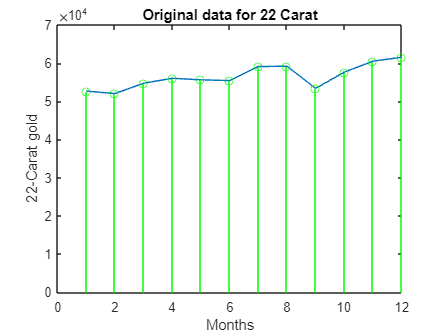


% Read the Excel file
dataTable = readtable("gr12.xlsx");

% Extract Month Name, High Temperature, and Low Temperature
months = dataTable.Months;
gold_22= dataTable.Carat22;
gold_24= dataTable.Carat24;

% Convert months to radians for Fourier transform
months_rad = (2 * pi * (1:numel(months))) / numel(months);

% Perform Fourier transform on low and high temperatures
gr22_fft = fft(gold_22);
gr24_fft = fft(gold_24);

% Correlation Analysis
cor22 = xcorr(gold_22);
cor24 = xcorr(gold_24);% Calculate autocorrelation for Gold price data

% Original data
figure;
plot((1:numel(months)),gold_22);
hold on;
stem(gold_22,'g');
xlabel('Months')
ylabel('22-Carat gold')
title('Original data for 22 Carat');
hold off;

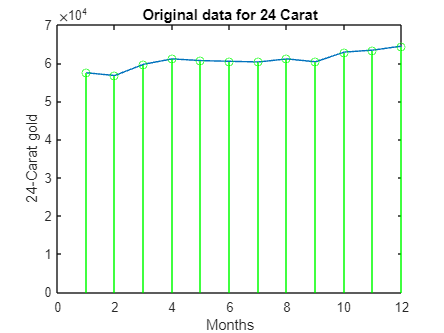


figure;
plot((1:numel(months)),gold_24);
hold on;
stem(gold_24,'g');
xlabel('Months')
ylabel('24-Carat gold')
title('Original data for 24 Carat');
hold off;

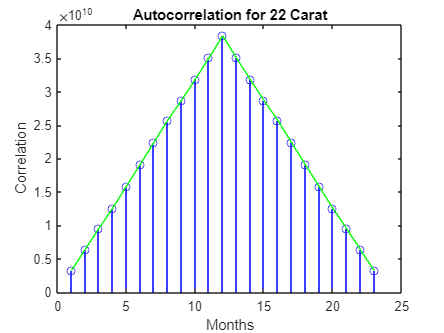


% correlation
figure;
stem(cor22, 'b');
hold on;
plot(cor22,'g');
xlabel('Months');
ylabel('Correlation');
title('Autocorrelation for 22 Carat');
hold off;

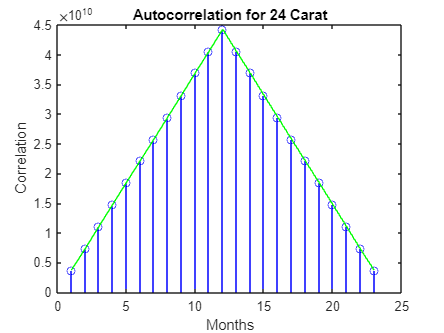


figure;
stem(cor24, 'b');
hold on;
plot(cor24,'g');
xlabel('Months');
ylabel('Correlation');
title('Autocorrelation for 24 Carat');
hold off;

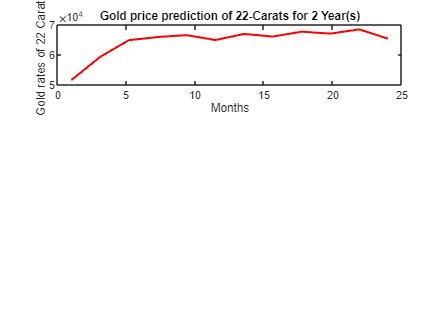

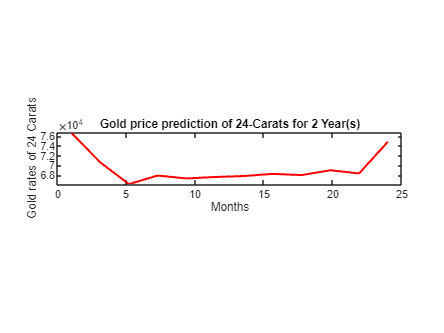

Maximum output for 2 Year(s):


    max_rate_22    max_rate_24
    ___________    ___________

       68481          76701   



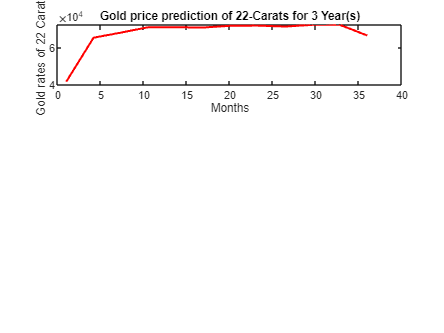

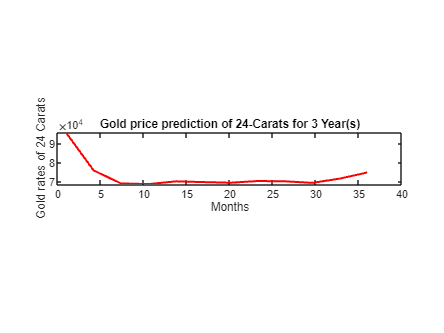

Maximum output for 3 Year(s):


    max_rate_22    max_rate_24
    ___________    ___________

       72272          95817   



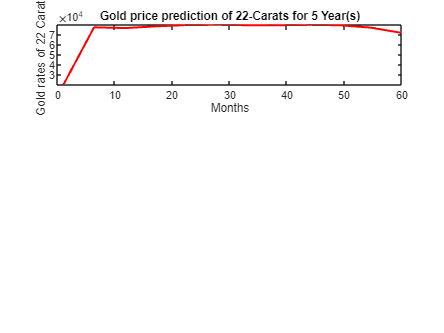

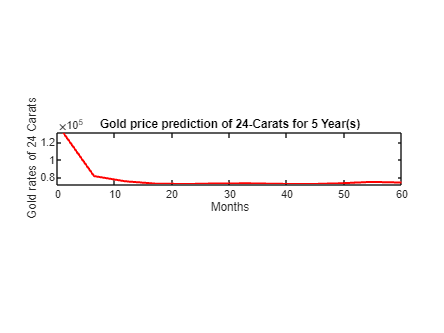

Maximum output for 5 Year(s):


    max_rate_22    max_rate_24
    ___________    ___________

       79762       1.3107e+05 




% Predictions for 1 year, 2 years, and 5 years
years_to_predict = [2,3,5]; % Change as needed

for i = 1:length(years_to_predict)
    % Generate new months for prediction
    predicted_months = linspace(1, (numel(months)*years_to_predict(i)),12);
    predicted_months_rad = (2 * pi * predicted_months) / (numel(months) + years_to_predict(i));
    
    % Interpolate low and high temperature data
    interpolated_gr22 = interp1(months_rad,gr22_fft, predicted_months_rad, 'linear', 'extrap');
    interpolated_gr24 = interp1(months_rad,gr24_fft, predicted_months_rad, 'linear', 'extrap');
    
    % Inverse Fourier transform to get predicted temperatures
    predicted_gr22 = ifft(interpolated_gr22);
    a=real(predicted_gr22);
    predicted_gr24 = ifft(interpolated_gr24);
    b=real(predicted_gr24);
 
    % Plot the predictions
    figure;
    subplot(3, 1, 1);
    plot(predicted_months,a, 'r', 'LineWidth', 1.5);
    xlabel('Months');
    ylabel('Gold rates of 22 Carats');
    title(['Gold price prediction of 22-Carats for ', num2str(years_to_predict(i)), ' Year(s)']);

       
    figure;
    subplot(3, 1, 2);
    plot(predicted_months,b, 'r', 'LineWidth', 1.5);
    xlabel('Months');
    ylabel('Gold rates of 24 Carats');
    title(['Gold price prediction of 24-Carats for ', num2str(years_to_predict(i)), ' Year(s)']);
 
    
    % Display maximum output data in a table
      max_rate_22=max(real(a));
      max_rate_24=max(real(b));
    max_table = table(max_rate_22,max_rate_24);
    disp(['Maximum output for ', num2str(years_to_predict(i)), ' Year(s):']);
    disp(max_table);
    
end